clear;
clc;

SISO Gaussian Proccess Regression

function K = Squared_Exponential_Kernel(x1, x2, signalstandarddeviation, characteristiclength)
    K = signalstandarddeviation^2*exp(-(pdist2(x1,x2,"euclidean").^2)/(2*characteristiclength^2));
    return
end
function C = Calculate_Covariance_Matrix(x, y, signalstandarddeviation, characteristiclength)
    covariance_matrix = zeros(length(x),length(y));
    y_range = 1:length(y);
    for i = 1:length(x)
        y_values = y;
        for j = y_range
            covariance_matrix(i,j) = Squared_Exponential_Kernel(x(i), y_values(j), signalstandarddeviation, characteristiclength);
        end
    end
    C = covariance_matrix;
    return
end
% function [mean_at_values, covar_matrix, variance, Sizes] = SISO_Gaussian_Proccess_Regression(data_x, data_y, test_locations, signalstandarddeviation, characteristiclength, noise)
%     K = Calculate_Covariance_Matrix(data_x,data_x, signalstandarddeviation, characteristiclength)+ ...
%         (noise+3e-6)*eye(length(data_x));
%     K_star = Calculate_Covariance_Matrix(data_x,test_locations, signalstandarddeviation, characteristiclength);
%     K_star2 = Calculate_Covariance_Matrix(test_locations,test_locations, signalstandarddeviation, characteristiclength);
%     K_Size = size(K)';
%     K_star_Size = size(K)';
%     K_star2_Size = size(K)';
%     Sizes = [K_Size, K_star_Size, K_star2_Size];
%     mean_at_values = K_star'/K*data_y;
%     covar_matrix = K_star2 - K_star'/K*K_star;
%     variance = diag(covar_matrix);
%     return
% end
% n = 100;
% true_x = linspace(-1,5,n)';
% true_y = 0.5*true_x;
% x_values = true_x+normrnd(0,0.1,n,1);
% y_values = true_y+normrnd(0,0.1,n,1);
% generation_locations = linspace(-5,10,100);
% signalstandarddeviation = 1;
% characteristiclength = 3;
% noise = 0.2;
% [mean_generated_values, ~, variance, ~] = SISO_Gaussian_Proccess_Regression(x_values,y_values,generation_locations, signalstandarddeviation, characteristiclength, noise);
% figure;
% hold on;
% x_fillplot = [generation_locations, fliplr(generation_locations)];
% for i = 5:-1:1
%     pm_sigma = [mean_generated_values'+i*sqrt(variance'),fliplr(mean_generated_values'-i*sqrt(variance'))];
%     fill(x_fillplot,pm_sigma,[1-0.5/i,1-0.5/i,1-0.5/i],'LineStyle','none')
% end
% plot(generation_locations,mean_generated_values,'k-');
% scatter(x_values,y_values,'rx');
% ylim([-6,6]);
% xlim([-3,8]);
% legend('\pm5\sigma','\pm4\sigma','\pm3\sigma','\pm2\sigma','\pm\sigma','Orientation','Horizontal','Location','South')

MISO Gaussian Proccess Regression Code 1

% function [DD, DT, TT] = Product_Covariance_Matrixes(data_matrix, test_matrix, signalstandarddeviation, characteristiclength)
%     DD = zeros(size(data_matrix,1),size(data_matrix,1),size(data_matrix,2))+1;
%     for k = 1:size(DD,3) % Target Selection
%         for i = 1:size(DD,1) % Input Data
%             for j = 1:size(DD,2) % Target Data
%                 for notk = 1:size(DD,3)
%                     if k ~= notk
%                         DD(i,j,k) = DD(i,j,k)*Squared_Exponential_Kernel(data_matrix(i,notk),data_matrix(j,k),signalstandarddeviation, characteristiclength);
%                     end
%                 end
%             end
%         end
%     end
%     DT = zeros(size(data_matrix,1),size(test_matrix,1),size(data_matrix,2));
%     for k = 1:size(DT,3) % Target Selection
%         for i = 1:size(DT,1) % Input Data
%             for j = 1:size(DT,2) % Target Data
%                 DT(i,j,k) = Squared_Exponential_Kernel(data_matrix(i,k),test_matrix(j,k),signalstandarddeviation, characteristiclength);
%             end
%         end
%     end
%     TT = zeros(size(test_matrix,1),size(test_matrix,1),size(data_matrix,2))+1;
%     return
% end
% true_x1 = linspace(0,10,100);
% true_x2 = true_x1;
% true_x3 = true_x1.*true_x2+1;
% n = length(true_x1);
% true_data_matrix = [true_x1',true_x2',true_x3'];
% noisy_data_matrix = true_data_matrix;% + normrnd(0,0.05,size(true_data_matrix));
% test_x1 = linspace(0,10,1000);
% test_x2 = test_x1;
% test_x3 = test_x1.*test_x2+1;
% test_data_matrix = [test_x1',test_x2',test_x3'];
% 
% signalstandarddeviation = 1;
% characteristiclength = 1;
% noise = 0;
% 
% [K, K_star, ~] = Product_Covariance_Matrixes(noisy_data_matrix, test_data_matrix,signalstandarddeviation,characteristiclength);
% K = K + (noise+3e-6)*eye(length(noisy_data_matrix));
% mean_at_values = zeros(size(test_data_matrix));
% for i = 1:1:size(test_data_matrix,2)
%     mean_at_values(:,i) = K_star(:,:,i)'/K(:,:,i)*noisy_data_matrix(:,i);
% end

MISO Gaussian Proccess Regression Code 2

function [ab_matrix] = DistanceSquareFunction(a_matrix,b_matrix)
    if size(a_matrix, 2) ~= size(b_matrix, 2)
        error("A & B Matrix Not Same Var Number")
    end
    a_number = size(a_matrix,1);
    b_number = size(b_matrix,1);
    ab_matrix = zeros(a_number,b_number);
    parfor a = 1:a_number
        b_matrix_local = b_matrix
        for b = 1:b_number
            ab_matrix(a,b) = sum((a_matrix(a,:)-b_matrix_local(b,:)).^2);
        end
    end
    return
end
function [result_matrix] = GassianRadialBasisFunction(a_matrix,b_matrix, shape)
    distance_square_matrix = DistanceSquareFunction(a_matrix,b_matrix);
    result_matrix = exp(-(distance_square_matrix.*shape).^2);
    return
end
function [K, Ks, Kss] = MISOGPR(training_data_matrix,test_data_matrix,shape)
    i_number = size(training_data_matrix, 2);
    training_number = size(training_data_matrix,1);
    test_number = size(test_data_matrix,1);
    K = zeros(training_number,training_number);
    Ks = zeros(training_number,test_number);
    Kss = zeros(test_number,test_number);
    for i = 1:1:i_number
        K(:,:,i) = GassianRadialBasisFunction(training_data_matrix,training_data_matrix,shape);
        Ks(:,:,i) =  GassianRadialBasisFunction(training_data_matrix,test_data_matrix,shape);
        Kss(:,:,i) = GassianRadialBasisFunction(test_data_matrix,test_data_matrix,shape);
    end
    return
end

MISO Gaussian Proccess Regression Test

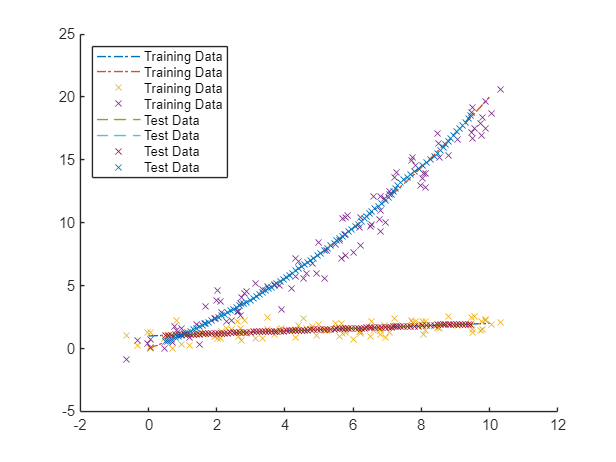

true_number = 100;
test_number = 100;
true_x1 = linspace(0,10,true_number);
true_x2 = true_x1/10+zeros(1,true_number)+1;
true_x3 = true_x1.*true_x2;
n = length(true_x1);
true_data_matrix = [true_x1',true_x2',true_x3'];
noisy_data_matrix = true_data_matrix + normrnd(0,0.5,size(true_data_matrix));
training_data_matrix = noisy_data_matrix;
test_x1 = linspace(0.5,9.5,test_number);
test_x2 = test_x1/10+zeros(1,test_number)+1;
test_x3 = test_x1.*test_x2;
test_data_matrix = [test_x1', test_x2', test_x3'];

[K, Ks, Kss] = MISOGPR(training_data_matrix,test_data_matrix,0.03);
% variance = diag(Kss(:,:,1) - Ks(:,:,1)'/K(:,:,1)*Ks(:,:,1))
mean = (Ks(:,:,1)'/(K(:,:,1)))*training_data_matrix;
% return
figure;
hold on;
xlim([-2,12]);
% ylim([-2,6]);
p1 = plot(true_data_matrix(:,1),true_data_matrix(:,2:3),'-.','DisplayName',"Training Data");
% p1.Color = "#A2142F";
s1 = scatter(training_data_matrix(:,1),training_data_matrix(:,2:3),'x','DisplayName',"Training Data");
% s1.MarkerEdgeColor = "#A2142F";
tp1 = plot(mean(:,1),mean(:,2:3),'--','DisplayName',"Test Data");
% tp1.Color = "#7E2F8E";
ts1 = scatter(mean(:,1),mean(:,2:3),'x','DisplayName',"Test Data");
% ts1.MarkerEdgeColor = "#7E2F8E";
legend('Location','northwest');

% p2 = plot(true_x2,true_x3,'-.');
% p2.Color = "#77AC30";
% s2 = scatter(noisy_data_matrix(:,2),noisy_data_matrix(:,2),'x');
% s2.MarkerEdgeColor = "#77AC30";
% tp2 = plot(test_data_matrix(:,2),mean_at_values(:,2),'--');
% tp2.Color = "#D95319";
% ts2 = scatter(test_data_matrix(:,2),mean_at_values(:,2),'x');
% ts2.MarkerEdgeColor = "#D95319";

% covar_matrix = K_star2 - K_star'/K*K_star;
% variance = diag(covar_matrix);
% [mean_at_values, covar_matrix, variance] = MIMO_Gaussian_Proccess_Regression(noisy_data_matrix,test_matrix,signalstandarddeviations,characteristiclengths,noises)

MIMO Gaussian Proccess Regression

% function [mean_at_values, covar_matrixes, variances] = MIMO_Gaussian_Proccess_Regression(data_matrix, test_matrix, signalstandarddeviations, characteristiclengths, noises)
%     mean_at_values = zeros(size(test_matrix));
%     covar_matrixes = zeros(size(data_matrix,1),size(data_matrix,1),size(data_matrix,2));
%     variances = zeros(size(test_matrix));
%     % [mean_generated_values, ~, variance, ~] = MISO_Gaussian_Proccess_Regression(x_values,y_values,generation_locations, signalstandarddeviation, characteristiclength, noise);
%     for i = 1:1:size(data_matrix,2)
%         [mean_at_values(:,i), covar_matrixes(:,:,i), variances(:,i)] = SISO_Gaussian_Proccess_Regression(data_matrix(:,1),data_matrix(:,i), test_matrix(:,1),signalstandarddeviations(i), characteristiclengths(i), noises(i));
%     end
%     return
% end